format shortG
AOAex = [0.11, 1.14, 2.17, 3.17, 4.26, ...
    5.29, 6.32, 7.33, 8.34, ...
    9.36, 10.34, 11.39];                      %  Angle of attack ° Experimental
AOA = [0,2,4,6,8,10];                        %  Angle of attack ° Simulation
Ly = [0.001228501, 0.005644971, 0.009075581, ...
    0.010497372, 0.012396143, 0.014543814]  % Lift force at different angle of attack N 

Ly =     0.0012285     0.005645    0.0090756     0.010497     0.012396     0.014544


Dx = [0.00034527,0.000170046, -6.27607E-05, ...
    -5.41682E-06, -0.000215176, -0.000356981] % Drag force at different angle of attack N

Dx =    0.00034527   0.00017005  -6.2761e-05  -5.4168e-06  -0.00021518  -0.00035698


AOAy = cosd(AOA);
AOAx = sind(AOA);

L = (Ly.*AOAy)-(Dx.*AOAx)                    %  Resultant lift 

L =     0.0012285    0.0056356    0.0090579      0.01044     0.012305     0.014385



U = 4.9;                                     %  Free stream velocity m/s2
P = 1.204;                                   %  density of the fluid kg/m3             
b = 0.004;                                   %  Airfoil wingspan m 
u = (1.81*10^-5);                            %  Flow speed (Velocity) m/s2
c = 0.305;                                   %  Chord length m  
Re = ((U*P*c)/(u))                           %  Reynolds number at any distance

Re =         99413



CL = ((L)/(0.5*P*U^2*b*c))                   % Lift coefficient equation Simulation

CL =      0.069667      0.31959      0.51366      0.59207      0.69783      0.81575


CLex = [0.122, 0.231, 0.403, 0.574,...
    0.693, 0.784, 0.873, 0.945,...           % Lift coefficient equation Experimental   
    1, 1.051, 1.09, 1.105]

CLex =         0.122        0.231        0.403        0.574        0.693        0.784        0.873        0.945            1        1.051         1.09        1.105


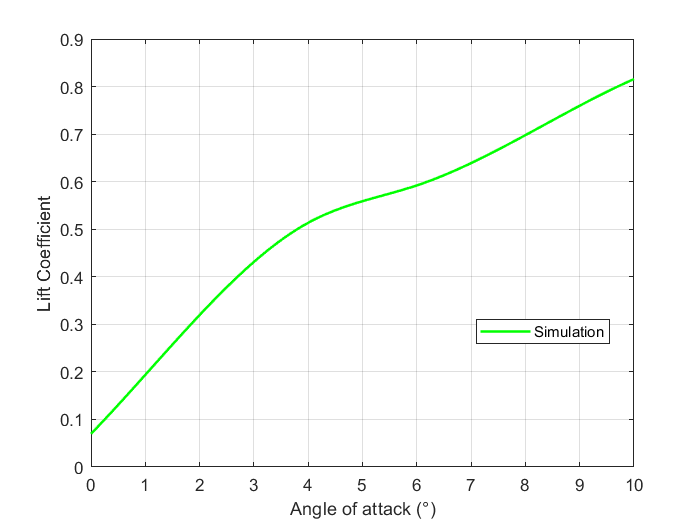


xi=linspace(min(AOA), max(AOA), 50);
yispl=interp1(AOA,CL,xi,'spline');

x2=linspace(min(AOAex), max(AOAex), 50);
yispL=interp1(AOAex,CLex,x2,'spline');


plot( xi,yispl,'g-','linewidth',1.5) 
xlabel('Angle of attack (°)');
ylabel('Lift Coefficient');                         
legend('Simulation','Location','best');
grid on; 

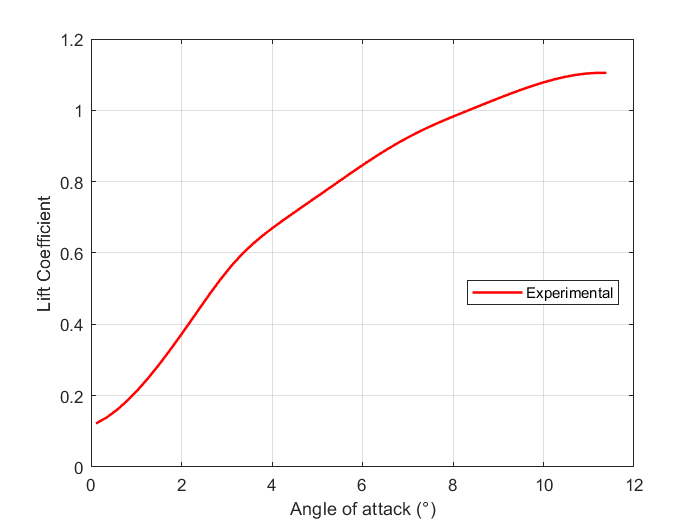


plot( x2,yispL,'r-','linewidth',1.5) 
xlabel('Angle of attack (°)');
ylabel('Lift Coefficient');                         
legend('Experimental','Location','best');
grid on; 

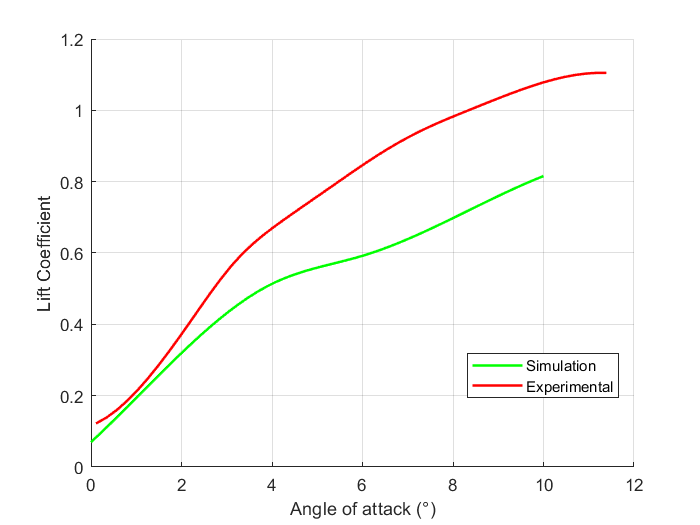


figure;
sp2 =subplot(1,1,1); 
hold on; 
plot( xi,yispl,'g-','linewidth',1.5) 
plot( x2,yispL,'r-','linewidth',1.5) 
xlabel('Angle of attack (°)');
ylabel('Lift Coefficient');                         
legend({'Simulation';'Experimental'},'Location','best');
grid on; 

F = [0 0.6 0.9 1.16 1.18 1.19 1.24 1.48 1.92 3.12 4.14 5.34 6.22 7.12 7.86 8.42];

E = [0 1.2 2.4 3.6 4.8 6.0 7.2 8.4 9.6 10.8 12.0 13.2 14.4 15.6 16.8 18];

xi=linspace(min(E), max(E), 50);

yispl=interp1(E,F,xi,'spline');

rest_length = 3;

total_length = 11.5;

stretch_length = total_length - rest_length;

ystretch=interp1(E,F,stretch_length,'spline');

subplot(1,1,1)

plot(E,F,'o', xi,yispl,'--')

hold on

xlabel('Stretched Length (in)')

ylabel('Force ()')

fprintf(1, '\n\tForce at total length = %.1f" (stretched length = %.1f") = %.2f\n\n', total_length, stretch_length, ystretch)

% Demo to show spline interpolation.

% Clean up / initialize

clc; 

close all; 

clear all; 

% Create the original knot points.

x = 1:10;

y = rand (10,1);

% Plot it and show how the line has sharp bends.

plot(x, y, '-sr', 'LineWidth', 2);

set(gcf, 'Position', get(0,'Screensize')); % Maximize figure.

% Use splines to interpolate a smoother curve,

% with 10 times as many points,

% that goes exactly through the same data points.

samplingRateIncrease = 10;

newXSamplePoints = linspace(1, 10, 10 * samplingRateIncrease);

smoothedY = spline(x, y, newXSamplePoints);

% Plot smoothedY and show how the line is

% smooth, and has no sharp bends.

hold on; % Don't destroy the first curve we plotted.

plot(newXSamplePoints, smoothedY, 'b-');

title('Spline Interpolation Demo', 'FontSize', 20);

legend('Original Points', 'Spline Points');

% Mathworks Demo code from their Help

% x = 0:10;

% y = sin(x);

% xx = 0:.25:10;

% yy = spline(x,y,xx);

% plot(x,y,'o',xx,yy)

.2 0.4 0.8 1.2 1.6 2.0];

y = [0 0.155 0.240 0.328 0.450 0.582 0.692];

p = polyfit(x, y, 1);

v = polyval(p, x);

S = x(:)\y(:)

plot(x,y,'o',x,S*x,'r-')

C = (x(:).^(1:4))\y(:);

xint = linspace(0,2,100)';

plot(x,y,'o',xint,(xint.^(1:4))*C,'r-')

spl = spline(x,y);

plot(x,y,'o',xint,ppval(spl,xint),'r-')